# Robust Hierarachical Moving Horizon Planner

The moving horizon planner provides a reference path and selects the operating region the controller should operate in. To calculate a safe passage—satisfy the constraints and avoid all obstacles—the planner takes the uncertainty bounds corresponding to the different operating modes directly into account.

## Definitions

### Define State-space Model

A double integrator model is used as the dynamics of the UAV. The equations are

$\begin{array}{l}
x_p \left(k+1\right)=A_p x_p \left(k\right)+B_p u_p \left(k\right)\\
y_p \left(k\right)={\textrm{Cx}}_p \left(k\right)
\end{array}$, where 


$$x_p =\left\lbrack \begin{array}{c}
x\\
\dot{x} \\
z\\
\dot{z} 
\end{array}\right\rbrack$$



$$u_p =\left\lbrack \begin{array}{c}
\ddot{x} \\
\ddot{z} 
\end{array}\right\rbrack$$


$y_p =\left\lbrack \begin{array}{c}
x\\
z
\end{array}\right\rbrack$.

clear
M=3;
dt = 0.01;

A_c = [1 dt 0 0;
       0 1  0 0;
       0 0  1 dt;
       0 0  0 1;];

A_p = A_c^M;

B_c = [dt^2/2 0;
       dt     0;
       0      dt^2/2;
       0      dt;];

B_p = zeros(size(B_c));
for i = 0:M-1
    B_p = B_p + A_c^i*B_c;
end

C_p = [1 0 0 0;
       0 0 1 0;];


### Define Square Obstacle Parameters


$$O_l =\left\lbrace y|E_l y\le f_l \right\rbrace$$


E_l = [1 0;
    -1 0;
     0 1;
     0 -1;];

f_l = [5.5;
    -4.5;
     5.5;
    -4.5;];


% For plotting
obs_x = [-f_l(2);
         f_l(1);
         f_l(1);
         -f_l(2);
         -f_l(2)];

obs_y = [-f_l(2);
         -f_l(2);
         f_l(1);
         f_l(1);
         -f_l(2)];

### Define MPC Parameters

alpha_x = 0.1;
alpha_u = 0.000001;
num_states = 4;
num_controls = 2;
num_modes = 2; % const for now
num_faces = 4;

N = 11;
x_goal = [20; 0; 20; 0];

% Define the number of decision variables
num_t_N = 1;
num_t_x = N-1;
num_t_u = N-1;
num_x_p = N * num_states;
num_u_p = (N-1) * num_controls;
total_vars = num_t_N + num_t_x + num_t_u + num_x_p + num_u_p + num_modes+num_faces*num_modes;

num_contraints = 2*(num_x_p+num_u_p)+num_modes*num_x_p/2+2*N*num_faces+2;

### Optimization 

The cost function (objective)


$$J_{\mathrm{p}}\left(\left\{x_p\right\},\left\{u_p\right\}\right)=\left\|x_{\text {goal }}-x_p\left(k_p+N\right)\right\|_{\infty}+\sum_{j=k_p}^{k_p+N-1} \alpha_x\left\|x_{\text {goal }}-x_p(j)\right\|_{\infty}+\alpha_u\left\|u_p(j)\right\|_{\infty}$$


can be rewriten as a linear program


$$J_{\mathrm{p}}=t_N+\sum_{j=k_p}^{k_p+N-1} \alpha_x t_x(j)+\alpha_u t_u(j)$$
 

with constraints

$
t_N \geq\left|x_{\text {goal }, i}-x_p\left(k_p+N\right)_i\right| \quad \forall i \\
t_x(j) \geq \alpha_x\left|x_{\text {goal }, i}-x_p(j)_i\right| \quad \forall i, \forall j \in\left[k_p, k_p+N-1\right] \\
t_u(j) \geq \alpha_u\left|u_p(j)_i\right| \quad \forall i, \forall j \in\left[k_p, k_p+N-1\right]
\end{gathered}$.

The MATLAB function intlinprog finds the minimum of a problem specified by

$\min _x f^T x \text { subject to }\left\{\begin{array}{l}
x \text { (intcon) are integers } \\
A \cdot x \leq b \\
A e q \cdot x=b e q \\
l b \leq x \leq u b .
\end{array}\right.$.

$x$ is definded implicitly as


$$x=\left\lbrack \begin{array}{c}
{\mathit{\mathbf{x}}}_p \left(k_p \right):{\mathit{\mathbf{x}}}_p \left(k_p +N\right)\\
{\mathit{\mathbf{u}}}_p \left(k_p \right):{\mathit{\mathbf{u}}}_p \left(k_p +N-1\right)\\
t_x \left(k_p \right):t_x \left(k_p +N-1\right)\\
t_N \\
t_u \left(k_p \right):t_u \left(k_p +N-1\right)\\
d_i \\
b_a^i 
\end{array}\right\rbrack$$
 

and $f$ is defined as

$f=$$\left\lbrack \begin{array}{c}
\left.0\cdot {\left(\mathit{\mathbf{x}}\right.}_p \left(k_p \right):{\mathit{\mathbf{x}}}_p \left(k_p +N\right)\right)\\
0\cdot \left({\mathit{\mathbf{u}}}_p \left(k_p \right):{\mathit{\mathbf{u}}}_p \left(k_p +N-1\right)\right)\\
\alpha_x \cdot \left(t_x \left(k_p \right):t_x \left(k_p +N-1\right)\right)\\
t_N \\
\alpha_u \cdot \left(t_u \left(k_p \right):t_u \left(k_p +N-1\right)\right)\\
0\cdot d_i \\
0\cdot b_a^i 
\end{array}\right\rbrack$.

Optimization variable $d_i$ is a binary variable to choose the low level control mode.

f = [zeros(num_x_p,1);
     zeros(num_u_p,1);
     alpha_x*ones(num_t_x,1);
     ones(num_t_N);
     alpha_u*ones(num_t_u,1);
     zeros(num_modes,1)
     zeros(num_modes*num_faces,1)];

The constraints 


$$\left|x_{\text {goal }, i}-x_p\left(k_p+N\right)_i\right| \leq t_N\quad \forall i \\
\left|x_{\text {goal }, i}-x_p(j)_i\right| \leq t_x(j) \quad \forall i, \forall j \in\left[k_p, k_p+N-1\right] \\
\left|u_p(j)_i\right| \leq t_u(j) \quad \forall i, \forall j \in\left[k_p, k_p+N-1\right]
\end{gathered}$$


are implement using matrix $A$ and vector $b$ in the equation

 $A \cdot x \leq b$.

The equations are rearrange to become compliant with the equation above:


$$\left\lbrack \begin{array}{c}
-x_p {\left(j\right)}_i -t_x \left(j\right)\le -x_{\textrm{goal},i} \;\;\;\;\;\forall i,\forall j\in \left\lbrack k_p ,k_p +N-1\right\rbrack \\
-x_p {\left(k_p +N\right)}_i -t_N \le -x_{\textrm{goal},i} \;\;\;\;\;\;\forall i\\
u_p {\left(j\right)}_i -t_u \left(j\right)\le 0\;\;\;\;\;\forall i,\forall j\in \left\lbrack k_p ,k_p +N-1\right\rbrack \\
x_p {\left(j\right)}_i -t_x \left(j\right)\le x_{\textrm{goal},i} \;\;\;\;\;\forall i,\forall j\in \left\lbrack k_p ,k_p +N-1\right\rbrack \\
x_p {\left(k_p +N\right)}_i -t_N \le x_{\textrm{goal},i} \;\;\;\;\;\;\forall i\\
{-u}_p {\left(j\right)}_i -t_u \left(j\right)\le 0\;\;\;\;\;\forall i,\forall j\in \left\lbrack k_p ,k_p +N-1\right\rbrack \\
x_p {\left(j\right)}_i +M_{\textrm{big}} d_i \le G+M_{\textrm{big}} \;\;\;\;\forall m\in \left\lbrack x_p {\left(j\right)}_m =\textrm{velocity}\right\rbrack ,\forall j\in \left\lbrack k_p ,k_p +N\right\rbrack \\
-E_a C_p x_p \left(k_p +j\right)-M_{\textrm{big}} b_a^i \le {-f}_a^i \\
\sum_{a=1:q} b_a^i +d_i \le q
\end{array}\right\rbrack$$


%% Manipulating matrix A and b

A = zeros(num_contraints,total_vars);
index = 1; % helper indexer

% row 1 & 2
A(1:num_x_p,1:num_x_p) = -eye(num_x_p,num_x_p);
for i = 1:N 
    A(index:index+num_states-1, num_x_p+num_u_p+i) = -ones(num_states,1);
    index = index + num_states;
end

% row 3
A(index:index+num_u_p-1,index:index+num_u_p-1) = eye(num_u_p,num_u_p);
for i = 1:N-1
    A(index:index+num_controls-1,num_x_p+num_u_p+N+i) = -ones(num_controls,1);
    index = index + num_controls;
end

% row 4 & 5
A(index:index+num_x_p-1,1:num_x_p) = eye(num_x_p,num_x_p);
for i = 1:N
    A(index:index+num_states-1, num_x_p+num_u_p+i) = -ones(num_states,1);
    index = index + num_states;
end

% row 6
A(index:index+num_u_p-1,num_x_p+1:num_x_p+num_u_p) = -eye(num_u_p,num_u_p);
for i = 1:N-1
    A(index:index+num_controls-1,num_x_p+num_u_p+N+i) = -ones(num_controls,1);
    index = index + num_controls;
end

d_start_index = num_x_p+num_u_p+num_t_x+num_t_N+num_t_u+1;
% row 7 & 8
M_big = 1000;
A(index:index+num_x_p/2-1,d_start_index) = M_big*ones(num_x_p/2,1);
for i = 2:2:num_x_p
    A(index,i) = 1;
    index = index + 1;
end
A(index:index+num_x_p/2-1,d_start_index+1) = M_big*ones(num_x_p/2,1);
for i = 2:2:num_x_p
    A(index,i) = 1;
    index = index + 1;
end

for i = 1:num_states:num_x_p
    A(index:index+num_faces-1,i:i+num_states-1) = -E_l*C_p;
    A(index:index+num_faces-1,d_start_index+num_controls:d_start_index+num_controls+num_faces-1) = -M_big*eye(num_faces,num_faces);
    index = index + num_faces;
end

for i = 1:num_states:num_x_p
    A(index:index+num_faces-1,i:i+num_states-1) = -E_l*C_p;
    A(index:index+num_faces-1,d_start_index+num_controls+num_faces:d_start_index+num_controls+2*num_faces-1) = -M_big*eye(num_faces,num_faces);
    index = index + num_faces;
end

A(index:index+1,d_start_index:d_start_index+1) = eye(num_modes,num_modes);
A(index,d_start_index+num_modes:d_start_index+num_modes+num_faces-1) = ones(1,num_faces);
A(index+1,d_start_index+num_modes+num_faces:d_start_index+num_modes+2*num_faces-1) = ones(1,num_faces);

b = zeros(num_contraints,1);
index = 1;
for i = 1:N
    b(index:index+num_states-1) = -x_goal;
    b(index+num_x_p+num_u_p:index+num_x_p+num_u_p+num_states-1) = x_goal;
    index = index + num_states;
end
index = index+num_x_p+2*num_u_p;
G1 = 50;
G2 = 100;
b(index:index+num_x_p/2-1) = G1 + M_big;
index = index + num_x_p/2;
b(index:index+num_x_p/2-1) = G2 + M_big;
index = index + num_x_p/2;

for i = 1:2*N
    b(index:index+num_faces-1) = -f_l;
    index = index +num_faces;
end
b(index:index+1) = num_faces*ones(num_modes,1);


To implement the double integrator dynamics, we use the equality constraint

$Aeq \cdot x = beq$.

We manipulate $\textrm{Aeq}$ and $\textrm{beq}$ to have equations


$$\left\lbrack \begin{array}{c}
x_p \left(k_p +j+1\right)-A_p x_p \left(k_p +j\right)-B_p u_p \left(k_p +j\right)\;\;\;\;\;\;\;\forall j\in \left\lbrack 0,\ldotp \ldotp \ldotp ,N-1\right\rbrack \\
x_p =\textrm{intial}\;\textrm{condition}\\
\sum_i d_i =1
\end{array}\right\rbrack$$


%% Manipulating Aeq and beq

Aeq = zeros(N*num_states+1, total_vars);

% Inserting x_p(k_p+j+1)
Aeq(1:(N-1)*num_states,num_states+1:N*num_states) = eye((N-1)*num_states,(N-1)*num_states);

% Inserting A_p in every equation
index = 1;
for i = 1:N-1
    Aeq(index:index+num_states-1,index:index+num_states-1) = -A_p;
    index = index + num_states;
end

% Initial condition
Aeq(index:index+num_states-1,1:num_states) = eye(num_states,num_states);
index = index + num_states;

%
Aeq(index,d_start_index:d_start_index+num_modes-1) = ones(1,num_modes);

% Inserting B_p in every equation
index_row = 1;
index_col = num_states*N+1;
for i = 1:N-1
    Aeq(index_row:index_row+num_states-1,index_col:index_col+num_controls-1) = -B_p;
    index_row = index_row + 4;
    index_col = index_col + 2;   
end

beq = zeros(N*num_states+1,1);
beq(end) = 1;

## Simulation

% Solve the linear program
sim_time = 100;
out = zeros(sim_time, num_states);
x_ref = zeros(M*sim_time, num_states);

for i = 1:sim_time
    sol = intlinprog(f, d_start_index:total_vars, A, b, Aeq, beq);
    out(i,:) = sol(5:8)';
    beq((N-1)*num_states+1:N*num_states) = sol(5:8);
    % calculate xref
    for j = 1:M
        x_ref((i-1)*M+j,:) = x_ref((i-1)*M+j,:) + (A_c^j*sol(1:4))';
        for m = 0:j-1
            x_ref((i-1)*M+j,:) = x_ref((i-1)*M+j,:) + (A_c^m*B_c*sol(num_x_p+1:num_x_p+num_controls))';
        end
    end
end

Running HiGHS 1.6.0: Copyright (c) 2023 HiGHS under MIT licence terms
Presolving model
282 rows, 89 cols, 624 nonzeros
262 rows, 85 cols, 582 nonzeros

Solving MIP model with:
   262 rows
   85 cols (1 binary, 8 integer, 0 implied int., 76 continuous)
   582 nonzeros

        Nodes      |    B&B Tree     |            Objective Bounds              |  Dynamic Constraints |       Work      
     Proc. InQueue |  Leaves   Expl. | BestBound       BestSol              Gap |   Cuts   InLp Confl. | LpIters     Time

         0       0         0   0.00%   -466.0005556    inf                  inf        0      0      0         0     0.0s
 R       0       0         0   0.00%   32.81819915     33.27758313        1.38%        0      0      0        86     0.1s

Symmetry detection completed in 0.0s
No symmetry present


Solving report
  Status            Optimal
  Primal bound      33.277583128
  Dual bound        33.277583128
  Gap               0% (tolerance: 0.01%)
  Solution status   feasible
  

### Plotting

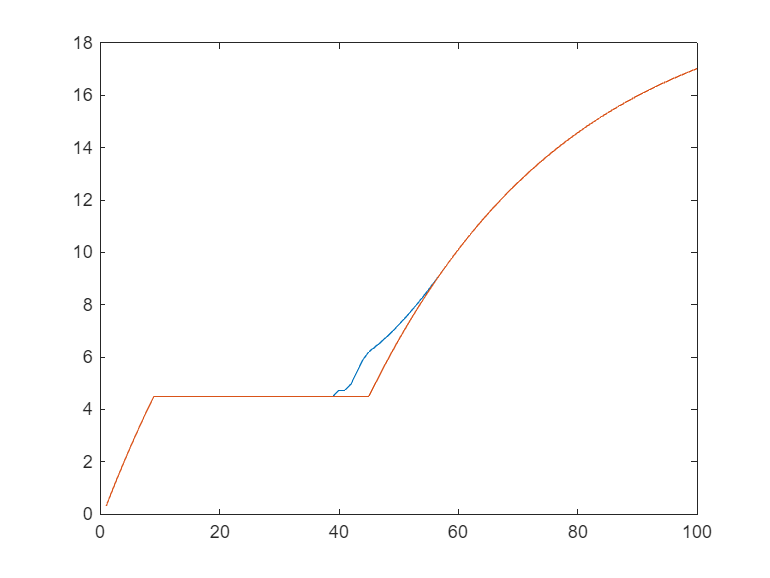

plot(1:length(out), out(:,1));
hold on;
plot(1:length(out), out(:,3));
hold off;

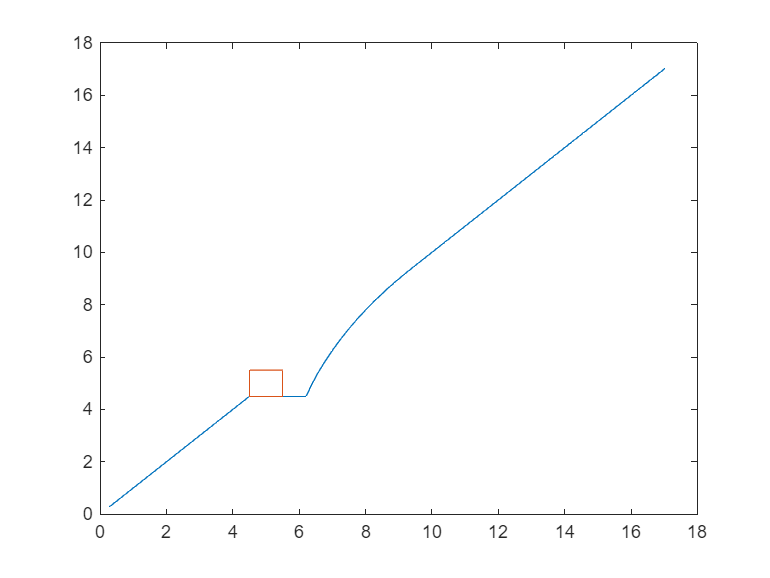


plot(out(:,1), out(:,3));
hold on;
plot(obs_x,obs_y);
hold off;